# Simulation을 위한 URDF 파일 불러오기

Matlab Robitcs 툴박스를 활용하여 ROS에서 활용되는 트리형 강체 모델을 불러올 수 있다. URDF 파일은 Xml 태그를 사용하여 강체의 물질, 공간 정보를 나타낸다. 자세한 내용은 ROS 홈페이지에서 URDF 설명 페이지를 보면 좋다.

## URDF 모델을 불러오기

snake = importrobot("description\snake.urdf")

snake =   rigidBodyTree - 속성 있음:

     NumBodies: 16
        Bodies: {1×16 cell}
          Base: [1×1 rigidBody]
     BodyNames: {'head'  '1_link'  '2_link'  '3_link'  '4_link'  '5_link'  '6_link'  '7_link'  '8_link'  '9_link'  '10_link'  '11_link'  '12_link'  '13_link'  '14_link'  '15_link'}
      BaseName: 'base_link'
       Gravity: [0 0 0]
    DataFormat: 'struct'


## 불러온 URDF 모델 보기

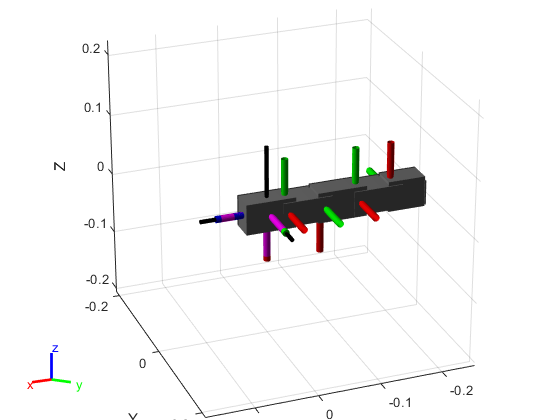

ans =   Axes (Primary) - 속성 있음:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  모든 속성 표시


show(snake)

보는 것과 같이 로봇 모델이 문제없이 불러온 것을 확인할 수 있다.

이후 Matlab과 연동하기 쉬운 Simscape 시뮬레이터에서 불러온 로봇을 이용하는 코드를 작성하자.

## Simscape에 URDF 모델 불러오기

Simscape는 URDF를 불러오기위해서 ``smimport`` 함수를 사용한다.

smimport(snake)